c = physconst("lightspeed");
d = dielectric("FR4");
d.EpsilonR = 4.4;
d.Thickness = 1.6e-3;
freq = 6.5e9;

l0=c/freq;
w=(l0/2)*(sqrt(2/(d.EpsilonR+1)))%width of the microstrip patch

w = 0.0140

x=w/d.Thickness;
ereff =((d.EpsilonR+1)/2)+(((d.EpsilonR-1)/2)*(1/sqrt(1+12*d.Thickness/w)));%effective diectric constant
dell =0.412*d.Thickness*(((ereff+0.3)*(x+0.264))/((ereff-0.258)*(x+0.8)));
lp=(l0/(2*sqrt(ereff)))-(2*dell)%physical length of the patch

lp = 0.0104

leff=lp+(2*dell)%effective length due to fringing fields

leff = 0.0118

p1 = patchMicrostripInsetfed;
p1.Length = lp;
p1.Width = w;
p1.Height = 1.4e-3;
p1.NotchLength = 3.3E-3;
p1.NotchWidth = 2.18E-3;
p1.FeedOffset = [-0.0200 0];
p1.GroundPlaneLength = 0.0400;
p1.GroundPlaneWidth = 0.0400;
p1.StripLineWidth = 1.2e-3

p1 =   patchMicrostripInsetfed with properties:

               Length: 0.0104
                Width: 0.0140
               Height: 0.0014
            Substrate: [1×1 dielectric]
    PatchCenterOffset: [0 0]
           FeedOffset: [-0.0200 0]
       StripLineWidth: 0.0012
          NotchLength: 0.0033
           NotchWidth: 0.0022
    GroundPlaneLength: 0.0400
     GroundPlaneWidth: 0.0400
            Conductor: [1×1 metal]
                 Tilt: 0
             TiltAxis: [1 0 0]
                 Load: [1×1 lumpedElement]


p1.Substrate = d;
p1

p1 =   patchMicrostripInsetfed with properties:

               Length: 0.0104
                Width: 0.0140
               Height: 0.0014
            Substrate: [1×1 dielectric]
    PatchCenterOffset: [0 0]
           FeedOffset: [-0.0200 0]
       StripLineWidth: 0.0012
          NotchLength: 0.0033
           NotchWidth: 0.0022
    GroundPlaneLength: 0.0400
     GroundPlaneWidth: 0.0400
            Conductor: [1×1 metal]
                 Tilt: 0
             TiltAxis: [1 0 0]
                 Load: [1×1 lumpedElement]


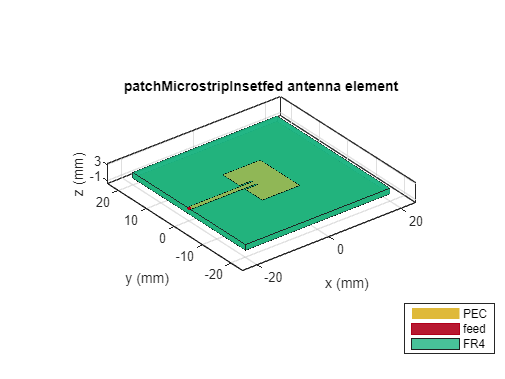

figure
show(p1)

pb1 = pcbStack(p1);

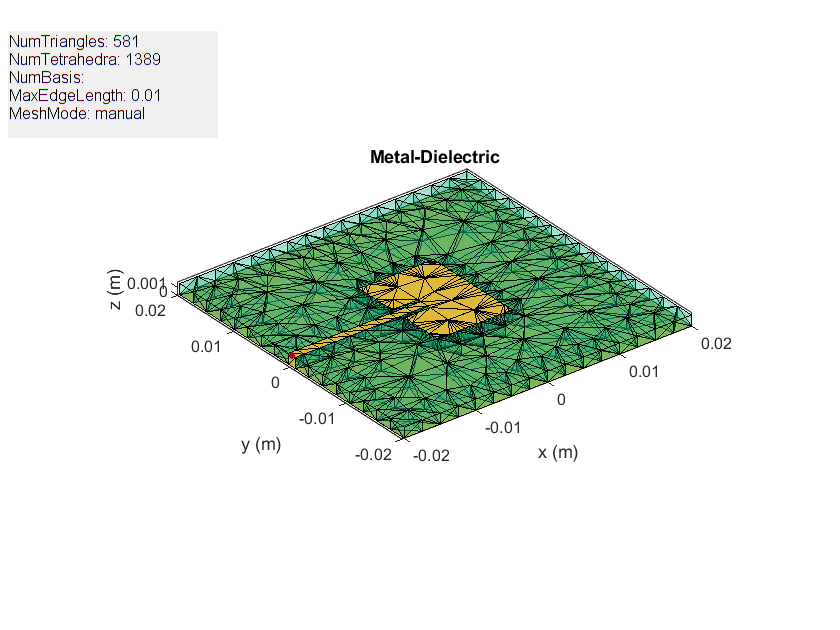

figure
mesh(pb1,MaxEdgeLength=0.01,MinEdgeLength=0.003)

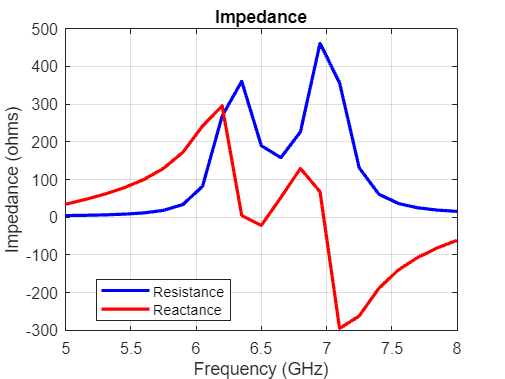

figure
impedance(pb1,linspace(5e9,8e9,21))

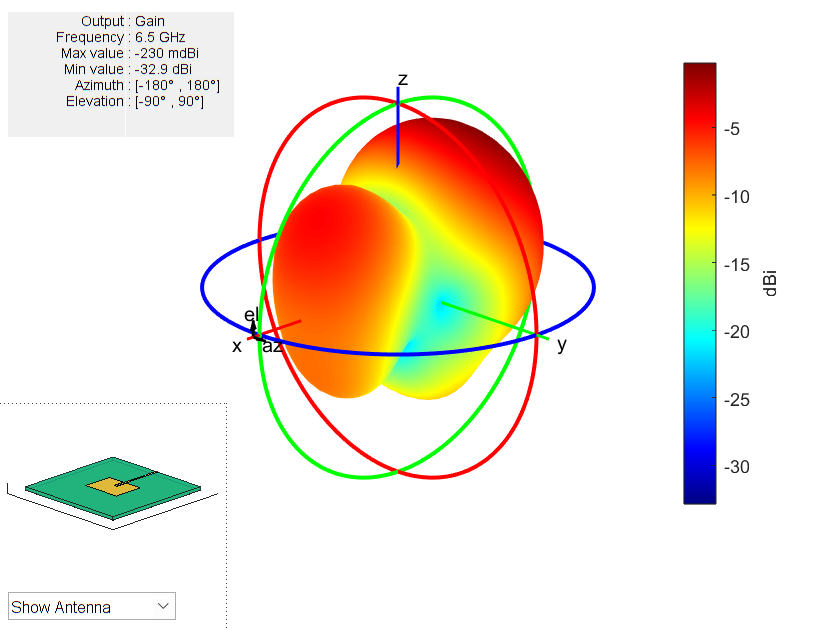

figure
pattern(pb1, freq)

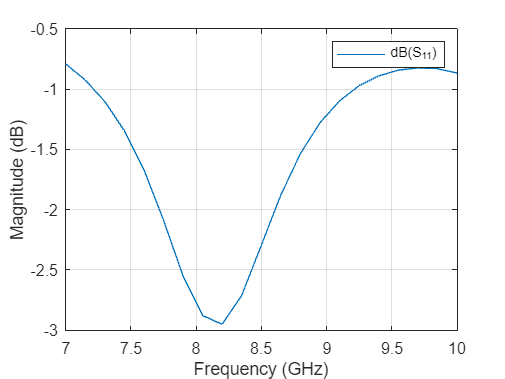

s = sparameters(pb1,linspace(7e9,10e9,21),50);
figure
rfplot(s,1,1)